close all

# Reguleringsteknik

## 1. System Analysis

#### Coefficients

theta = 0; % Angle to linearize around
m = 2; % kg

### **State space model**

System matrix

A = [cos(theta) 0;
     sin(theta) 0];

Input matrix

Linearisere omkring 0 rad

B = [cos(theta)*1 0;
     0            1/m];

Output matrix

C = [1 0]; 

## 2. LQR design

Text

% Control Law
Q = [1 0;  % Penalize X
     0 1]; % Penalize Y
R = 1;     % Penalize effort
K = lqr(A, B, Q, R);

Closed loop system

sys = ss((A - B*K), B, C, 0);

## 3. Simulation

Initial Conditions

x0 = [-0.1;  % x
      0.2]; % y

Run response to initial condition

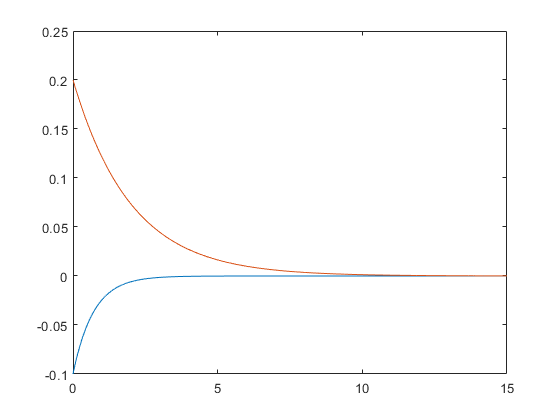

t = 0:0.01:15;
[~, t, data] = initial(sys, x0, t);
plot(t, data)

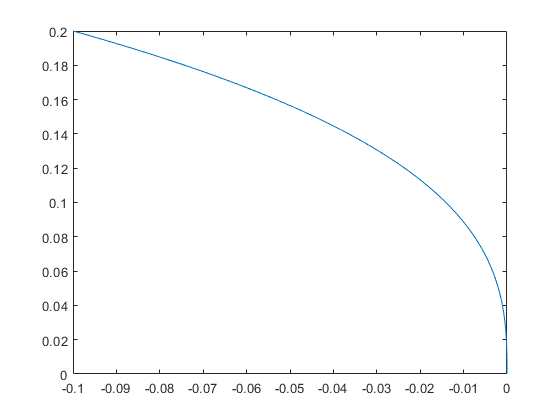



data_x = data(:,1);
data_y = data(:,2);
plot(data_x, data_y)

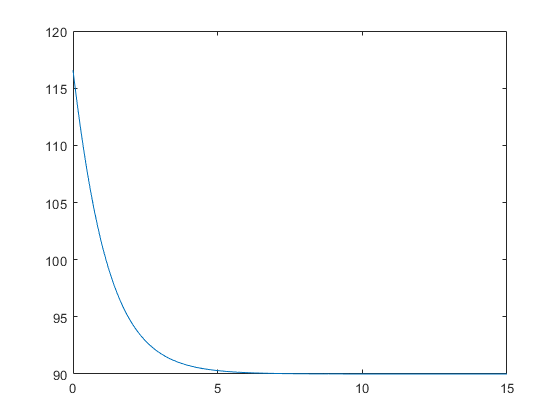


theta = rad2deg(atan2(data_y, data_x));
plot(t, theta)